Guião 1

Exercício 1 - 

experiencia = rand(3, 100000);

lancamentos = experiencia < 0.5;

numCaras = sum(lancamentos);

sucessos = numCaras == 2;

probabilidade = sum(sucessos) / 100000

probabilidade = 0.3760


% 2 Opção

N= 1e5; %número de experiências
p = 0.5; %probabilidade de cara
k = 2; %número de caras
n = 3; %número de lançamentos

lancamentos = rand(n,N) < p;
sucessos= sum(lancamentos)==k;
probSimulacao1= sum(sucessos)/N

probSimulacao1 = 0.3743

Exercício 2 - 

N= 1e5; %número de experiências
p = 0.5; %probabilidade de cara
k = 6; %número de caras
n = 15; %número de lançamentos

lancamentos = rand(n,N) < p;
sucessos= sum(lancamentos)==k;
probSimulacao2= sum(sucessos)/N

probSimulacao2 = 0.1515

Exercício 3 - 

N= 1e5; %número de experiências
p = 0.5; %probabilidade de cara
k = 6; %número de caras
n = 15; %número de lançamentos

lancamentos = rand(n,N) < p;
sucessos= sum(lancamentos)>=k;
probSimulacao3= sum(sucessos)/N

probSimulacao3 = 0.8501

Exercício 4 - 

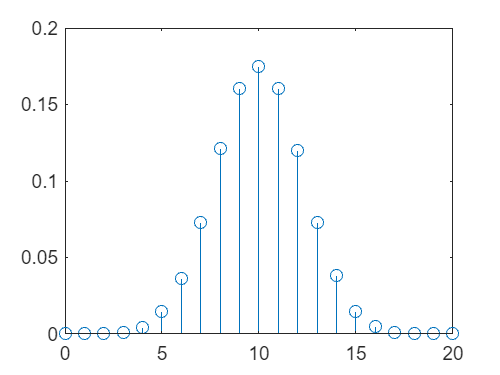

%20 Lançamentos
N= 1e5; %número de experiências
p = 0.5; %probabilidade de cara
k = 6; %número de caras
n = 20; %número de lançamentos
    
vp = zeros(1, n+1);
for k = 0:n
    vp(k+1) = prob(k, n, p, N);
end
stem(0:n, vp)

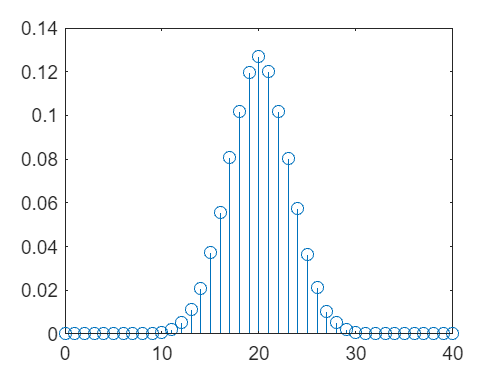

%40 Lançamentos
N= 1e5; %número de experiências
p = 0.5; %probabilidade de cara
k = 6; %número de caras
n = 40; %número de lançamentos
    
vp = zeros(1, n+1);
for k = 0:n
    vp(k+1) = prob(k, n, p, N);
end
stem(0:n, vp)

%100 Lançamentos
N= 1e5; %número de experiências
p = 0.5; %probabilidade de cara
k = 6; %número de caras
n = 100; %número de lançamentos
    
vp = zeros(1, n+1);
for k = 0:n
    vp(k+1) = prob(k, n, p, N);
end
stem(0:n, vp)

Exercício 5 - 

N= 1e5; %número de experiências
p = 0.5; %probabilidade de cara
k = 6; %número de caras
n = 15; %número de lançamentos

probSimulacao5 = prob(k,n,p,N)

%Cálculo Teórico
probTeorica5 = probTeorico(k,n,p)

Exercício 6 - 

%Alinea A - 
N= 1e5; %número de experiências
p = 0.3; %probabilidade de ser produzida com defeito
k = 3; %número de peça defeituosas
n = 5; %amostra de peças

probSimulacao6a = prob(k,n,p,N)

probSimulacao6a = 0.1326


%Cálculo Teórico
probTeorica6a = probTeorico(k,n,p)

probTeorica6a = 0.1323


%Alinea b - 
k = 2; %número de peça defeituosas

lancamentos = rand(n,N) < p;
sucessos= sum(lancamentos)<=k;
probSimulacao6b= sum(sucessos)/N

probSimulacao6b = 0.8382


probSimulacao6aIgual2 = prob(k,n,p,N)

probSimulacao6aIgual2 = 0.3083


%Cálculo Teórico
probTeorica6b = probTeorico(k,n,p)

probTeorica6b = 0.3087


%Alinea c -

vp = zeros(1, n+1);
for k = 0:n
    vp(k+1) = prob(k, n, p, N);

    fprintf("ProbSimulacao -> %.10f \n", prob(k, n, p, N));
end

ProbSimulacao -> 0.1683700000 
ProbSimulacao -> 0.3613800000 
ProbSimulacao -> 0.3096300000 
ProbSimulacao -> 0.1326000000 
ProbSimulacao -> 0.0285200000 
ProbSimulacao -> 0.0024400000 


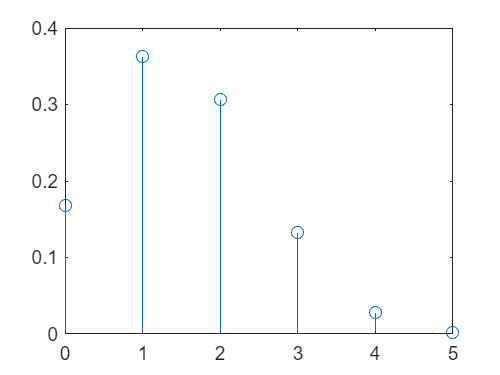

stem(0:n, vp)